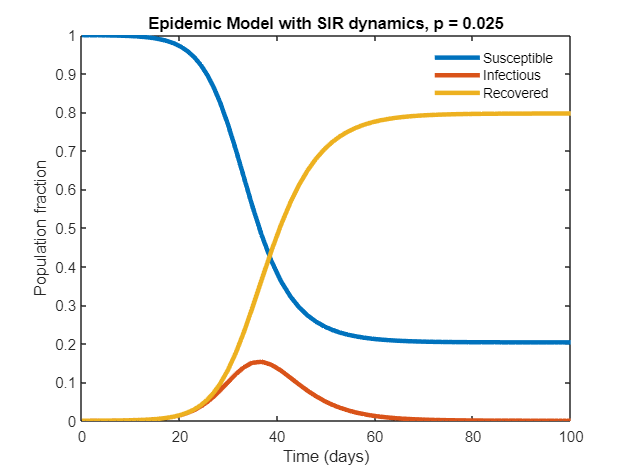

% main data goes here
pars.c = 20; % Contacts per unit time (e.g., days)
pars.p = 0.025; % Probability of infectious contact
pars.beta = pars.c*pars.p ;% Transmission rate
pars.gamma = 1/4; % Recovery rate (days^-1)
pars.R0 = 60;
pars.N = 10000;
pars.I0= 1;
pars.S0= pars.N-pars.I0;
% Run the model
[t,y]=ode45(@(t,y) sir_model(t,y,pars),[0 100],[pars.S0 pars.I0 0]/pars.N);
% Plot the results
tmph=plot(t,y);
set(tmph,'linewidth',3);
xlabel('Time (days)');
ylabel('Population fraction');
title('Epidemic Model with SIR dynamics, p = 0.025');
tmplh = legend('Susceptible','Infectious','Recovered');
legend('boxoff');

% Complete the simulation code below for the spread of an infectious disease beginning
% with 1 individual out of 10000 and estimate the value of R0. And run the code. Do you expect the disease
% to spread or not? Then, change the value of p to 0.01 { will the disease spread, why or why not? (expecting
% two plots)

% answer: When there is only one individual out of 10000 who is infectious
% the respective R0 value was estimated to be 0. After running the code and after 100 days,
% the fraction of population who are susceptible are 30%, the fraction of
% population who are recovered are 80%, and the fraction of people are are
% infectious increased to 20% but eventually reaches a steady state of 0%.
% This signifies spreading of the disease, especially when susceptible
% rates start to drop, coordinating with a rise in infectious rates, and
% then more and more people being recovered. 
% With these parameters, I expect the disease to spread. 

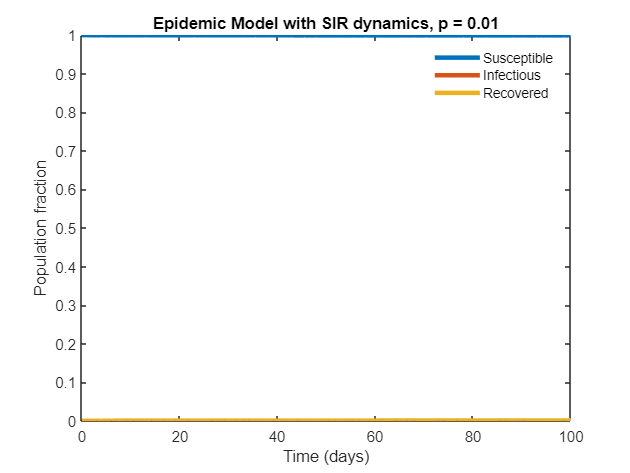

% main data goes here
pars.c = 20; % Contacts per unit time (e.g., days)
pars.p = 0.01; % Probability of infectious contact
pars.beta = pars.c*pars.p ;% Transmission rate
pars.gamma = 1/4; % Recovery rate (days^-1)
pars.R0 = 60;
pars.N = 10000;
pars.I0= 1;
pars.S0= pars.N-pars.I0;
% Run the model
[t,y]=ode45(@(t,y) sir_model(t,y,pars),[0 100],[pars.S0 pars.I0 0]/pars.N);
% Plot the results
tmph=plot(t,y);
set(tmph,'linewidth',3);
xlabel('Time (days)');
ylabel('Population fraction');
title('Epidemic Model with SIR dynamics, p = 0.01');
tmplh = legend('Susceptible','Infectious','Recovered');
legend('boxoff');


%reset pars.p 
pars.p = 0.025;

% The disease will not spread because we have decreased the probability of
% infectious contact by 0.025 - 0.01 / 0.025 = 0.6 or 60%. This means that
% less people are going to be infected upon the same number of contacts as
% before. Looking at the epidemic model, the fraction of susceptible remains
% at 1 and no one is getting infected, thus no one need to recover (0),
% thereby the disease is not spreading. 

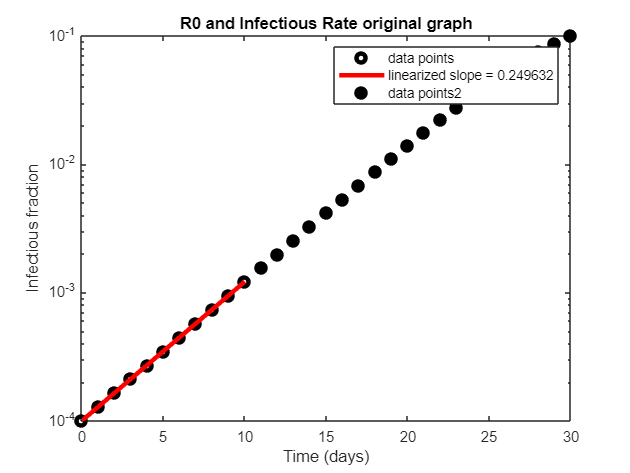

%Exercise 2 

% main data goes here
pars.c = 20; % Contacts per unit time (e.g., days)
pars.p = 0.01; % Probability of infectious contact
pars.beta = 0.5;% Transmission rate
pars.gamma = 1/4; % Recovery rate (days^-1)
pars.R0 = 1.625;
pars.N = 10000;
pars.I0= 1;
pars.S0= pars.N-pars.I0;

% Run the model over 10 days
[t,y]=ode45(@(t,y) sir_model(t,y,pars),0:1:10,[pars.S0 pars.I0 0]/pars.N);
% Find the slope
[p,s]=polyfit(t,log(y(:,2)),1);
c = polyfit(t,log(y(:,2)),1); 
% Plot the data and overlay the best-fit exponential
tmph=semilogy(t,y(:,2),'ko');
set(tmph,'linewidth',3);
hold on
tmph=semilogy(t,exp(p(1)*t+p(2)),'r-');
set(tmph,'linewidth',3);
% Use solid points for the future k
[t,y]=ode45(@(t,y) sir_model(t,y,pars),0:1:30,[pars.S0 pars.I0 0]/pars.N);
tmpi=find(t>10);
tmph=semilogy(t(tmpi),y(tmpi,2),'ko');
set(tmph,'linewidth',3,'markerfacecolor','k');
xlabel('Time (days)');
ylabel('Infectious fraction'); 
title('R0 and Infectious Rate original graph');
legend('data points', sprintf('linearized slope = %f', c(1)), 'data points2');

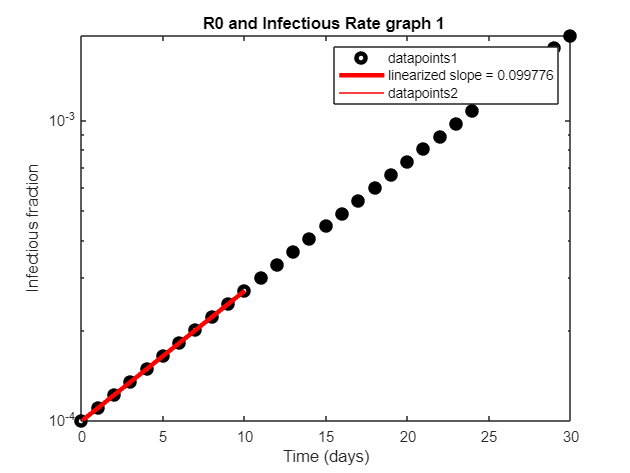

%% plot 1 
% main data goes here
pars.c = 20; % Contacts per unit time (e.g., days)
pars.p = 0.01; % Probability of infectious contact
pars.beta = 0.5;% Transmission rate
pars.gamma = 0.4; % Recovery rate (days^-1)
pars.R0 = 1.025;
pars.N = 10000;
pars.I0= 1;
pars.S0= pars.N-pars.I0;

% Run the model over 10 days
[t,y]=ode45(@(t,y) sir_model(t,y,pars),0:1:10,[pars.S0 pars.I0 0]/pars.N);
% Find the slope
[p,s]=polyfit(t,log(y(:,2)),1);
c = polyfit(t,log(y(:,2)),1); 
% Plot the data and overlay the best-fit exponential
tmph=semilogy(t,y(:,2),'ko');
set(tmph,'linewidth',3);
hold on
tmph=semilogy(t,exp(p(1)*t+p(2)),'r-');
f = semilogy(t,exp(p(1)*t+p(2)),'r-');
set(tmph,'linewidth',3);

% Use solid points for the future k
[t,y]=ode45(@(t,y) sir_model(t,y,pars),0:1:30,[pars.S0 pars.I0 0]/pars.N);
tmpi=find(t>10);
tmph=semilogy(t(tmpi),y(tmpi,2),'ko');
set(tmph,'linewidth',3,'markerfacecolor','k');
hold on
xlabel('Time (days)');
ylabel('Infectious fraction'); 
title('R0 and Infectious Rate graph 1 ');
legend('datapoints1', sprintf('linearized slope = %f', c(1)), 'datapoints2');

## the expected r values and R0 values are as follows:

%%Transmission (beta)  Recovery (gamma)   Strength(R0)   Speed(r)    
%%    0.5                    0.4             1.25         0.10
%%     1                     0.5             2             0.5
%%    0.25                   0.5             0.5           -0.25
%%    0.75                   0.25             3             0.5


% We can calculate strength R0 by the equation given as r = gamma*(R0 -1)
% or =recovery rate * (unitless strength -1), the strength here is r0 =
% r/gamma + 1 

## plot 2

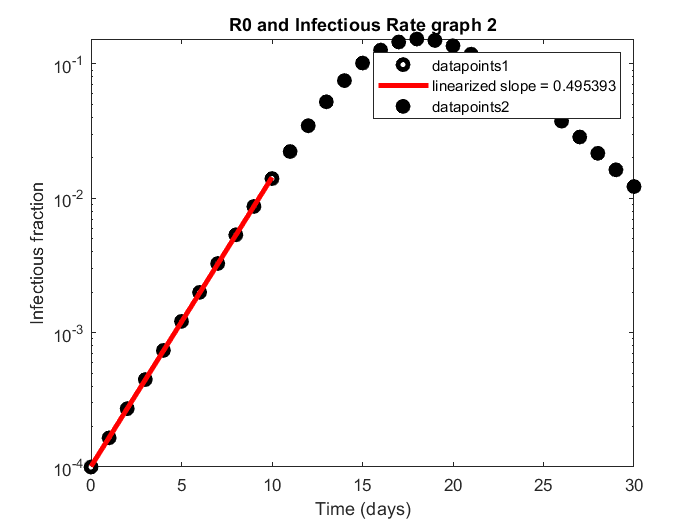

% main data goes here
pars.c = 20; % Contacts per unit time (e.g., days)
pars.p = 0.01; % Probability of infectious contact
pars.beta = 1;% Transmission rate
pars.gamma = 0.5; % Recovery rate (days^-1)
pars.R0 = 2;
pars.N = 10000;
pars.I0= 1;
pars.S0= pars.N-pars.I0;

% Run the model over 10 days
[t,y]=ode45(@(t,y) sir_model(t,y,pars),0:1:10,[pars.S0 pars.I0 0]/pars.N);
% Find the slope
[p,s]=polyfit(t,log(y(:,2)),1);
c = polyfit(t,log(y(:,2)),1); 
% Plot the data and overlay the best-fit exponential
tmph=semilogy(t,y(:,2),'ko');

set(tmph,'linewidth',3);
hold on
tmph=semilogy(t,exp(p(1)*t+p(2)),'r-');
%f = semilogy(t,exp(p(1)*t+p(2)),'r-');
set(tmph,'linewidth',3);
% Use solid points for the future k
[t,y]=ode45(@(t,y) sir_model(t,y,pars),0:1:30,[pars.S0 pars.I0 0]/pars.N);
tmpi=find(t>10);
tmph=semilogy(t(tmpi),y(tmpi,2),'ko');
set(tmph,'linewidth',3,'markerfacecolor','k');
hold off
xlabel('Time (days)');
ylabel('Infectious fraction'); 
title('R0 and Infectious Rate graph 2');
legend('datapoints1', sprintf('linearized slope = %f', c(1)), 'datapoints2');

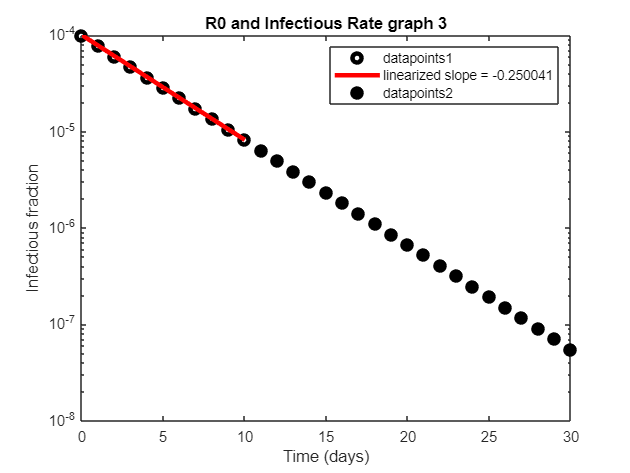

% graph 3 
% main data goes here
pars.c = 20; % Contacts per unit time (e.g., days)
pars.p = 0.01; % Probability of infectious contact
pars.beta = 0.25;% Transmission rate
pars.gamma = 0.5; % Recovery rate (days^-1)
pars.R0 = 0.5; 
pars.N = 10000;
pars.I0= 1;
pars.S0= pars.N-pars.I0;

% Run the model over 10 days
[t,y]=ode45(@(t,y) sir_model(t,y,pars),0:1:10,[pars.S0 pars.I0 0]/pars.N);
% Find the slope
[p,s]=polyfit(t,log(y(:,2)),1);
c = polyfit(t,log(y(:,2)),1); 
% Plot the data and overlay the best-fit exponential
tmph=semilogy(t,y(:,2),'ko');
set(tmph,'linewidth',3);
hold on
tmph=semilogy(t,exp(p(1)*t+p(2)),'r-');
%f = semilogy(t,exp(p(1)*t+p(2)),'r-');
set(tmph,'linewidth',3);
% Use solid points for the future k
[t,y]=ode45(@(t,y) sir_model(t,y,pars),0:1:30,[pars.S0 pars.I0 0]/pars.N);
tmpi=find(t>10);
tmph=semilogy(t(tmpi),y(tmpi,2),'ko');
set(tmph,'linewidth',3,'markerfacecolor','k');
hold off
xlabel('Time (days)');
ylabel('Infectious fraction'); 
title('R0 and Infectious Rate graph 3');
legend('datapoints1', sprintf('linearized slope = %f', c(1)), 'datapoints2');

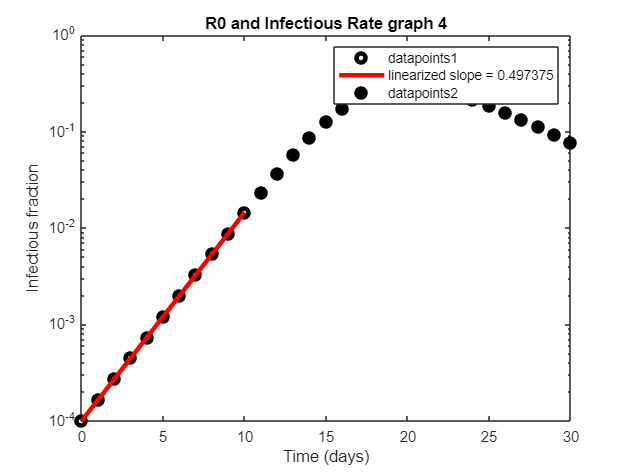

%plot 4 
% main data goes here
pars.c = 20; % Contacts per unit time (e.g., days)
pars.p = 0.01; % Probability of infectious contact
pars.beta = 0.75;% Transmission rate
pars.gamma = 0.25; % Recovery rate (days^-1)
pars.R0 = 1.025;
pars.N = 10000;
pars.I0= 1;
pars.S0= pars.N-pars.I0;

% Run the model over 10 days
[t,y]=ode45(@(t,y) sir_model(t,y,pars),0:1:10,[pars.S0 pars.I0 0]/pars.N);
% Find the slope
[p,s]=polyfit(t,log(y(:,2)),1);
c = polyfit(t,log(y(:,2)),1); 
% Plot the data and overlay the best-fit exponential
tmph=semilogy(t,y(:,2),'ko');
set(tmph,'linewidth',3);
hold on
tmph=semilogy(t,exp(p(1)*t+p(2)),'r-');
%f = semilogy(t,exp(p(1)*t+p(2)),'r-');
set(tmph,'linewidth',3);
% Use solid points for the future k
[t,y]=ode45(@(t,y) sir_model(t,y,pars),0:1:30,[pars.S0 pars.I0 0]/pars.N);
tmpi=find(t>10);
tmph=semilogy(t(tmpi),y(tmpi,2),'ko');
set(tmph,'linewidth',3,'markerfacecolor','k');
hold off
xlabel('Time (days)');
ylabel('Infectious fraction'); 
title('R0 and Infectious Rate graph 4');
legend('datapoints1', sprintf('linearized slope = %f', c(1)), 'datapoints2');

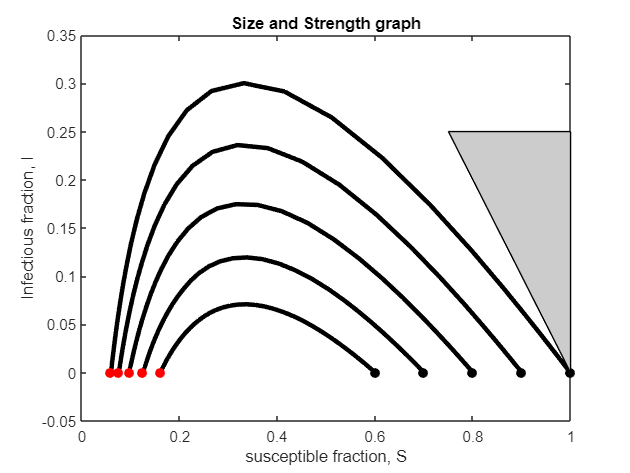

% Exercise 3

% Modify the initial values
pars.N = 10000;
pars.S0_range=[0.6 0.7 0.8 0.9 0.999];
pars.I0_range=1/pars.N*ones(1,5);
pars.R0_range=1-pars.S0_range-pars.I0_range;
% Run the model
for i=1:length(pars.S0_range),
[t,y]=ode45(@(t,y) sir_model(t,y,pars),[0:1:200],[pars.S0_range(i) pars.I0_range(i) pars.R0_range(i)]);
tmph=plot(y(:,1),y(:,2),'k-');
set(tmph,'linewidth',3);
hold on
tmph=plot(y(end,1),y(end,2),'ro');
set(tmph,'markerfacecolor','r');
tmph=plot(y(1,1),y(1,2),'ko');
set(tmph,'markerfacecolor','k');
end

xlabel('susceptible fraction, S'); 
ylabel('Infectious fraction, I'); 
title('Size and Strength graph');
% Show the excluded regime
patch([1 1 0.75 1],[0 0.25 0.25 0],[0.8 0.8 0.8]);

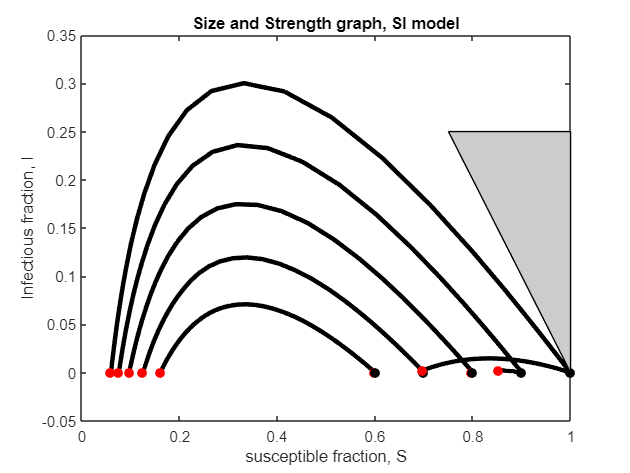

% main data goes here
pars.c = 20; % Contacts per unit time (e.g., days)
pars.p = 0.01; % Probability of infectious contact
pars.beta = 0.3;% Transmission rate
pars.gamma = 0.25; % Recovery rate (days^-1)
pars.R0 = 1.2;
pars.N = 10000;
pars.I0= 1;
pars.S0= pars.N-pars.I0;


% Modify the initial values
pars.N = 10000;
pars.S0_range=[0.6 0.7 0.8 0.9 0.999];
pars.I0_range=1/pars.N*ones(1,5);
pars.R0_range=1-pars.S0_range-pars.I0_range;
% Run the model
for i=1:length(pars.S0_range),
[t,y]=ode45(@(t,y) sir_model(t,y,pars),[0:1:200],[pars.S0_range(i) pars.I0_range(i) pars.R0_range(i)]);
tmph=plot(y(:,1),y(:,2),'k-');
set(tmph,'linewidth',3);
hold on
tmph=plot(y(end,1),y(end,2),'ro');
set(tmph,'markerfacecolor','r');
tmph=plot(y(1,1),y(1,2),'ko');
set(tmph,'markerfacecolor','k');
xlabel('susceptible fraction, S'); 
ylabel('Infectious fraction, I'); 
title('Size and Strength graph, SI model');

end
% Show the excluded regime
patch([1 1 0.75 1],[0 0.25 0.25 0],[0.8 0.8 0.8]);

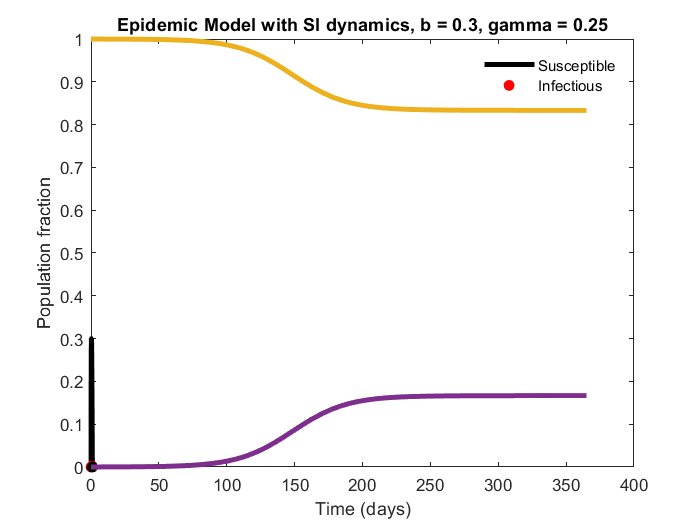

% main data goes here
pars.c = 20; % Contacts per unit time (e.g., days)
pars.p = 0.01; % Probability of infectious contact
pars.beta = 0.3;% Transmission rate
pars.gamma = 0.25; % Recovery rate (days^-1)
pars.R0 = 1.2; 
pars.N = 10000;
pars.I0= 1;
pars.S0= pars.N-pars.I0;

% Run the model
[t,y]=ode45(@(t,y) si_model(t,y,pars),[0 365],[pars.S0 pars.I0]/pars.N);
% Plot the results
tmph=plot(t,y);
set(tmph,'linewidth',3);
xlabel('Time (days)');
ylabel('Population fraction');
title('Epidemic Model with SI dynamics, b = 0.3, gamma = 0.25');
tmplh = legend('Susceptible','Infectious');
legend('boxoff');

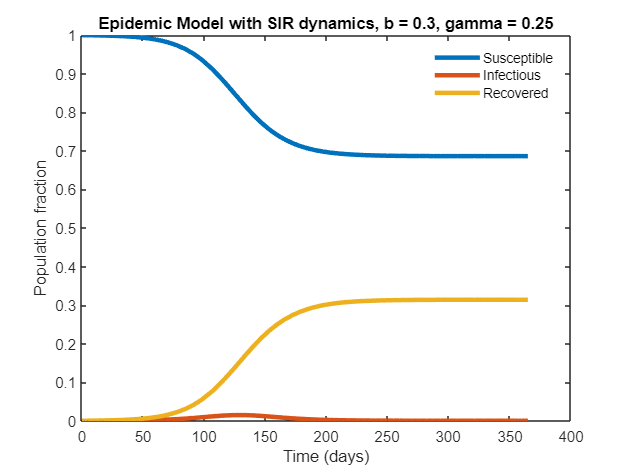

% main data goes here
pars.c = 20; % Contacts per unit time (e.g., days)
pars.p = 0.01; % Probability of infectious contact
pars.beta = 0.3;% Transmission rate
pars.gamma = 0.25; % Recovery rate (days^-1)
pars.R0 = 1.2; 
pars.N = 10000;
pars.I0= 1;
pars.S0= pars.N-pars.I0;

% Run the model
[t,y]=ode45(@(t,y) sir_model(t,y,pars),[0 365],[pars.S0 pars.I0 0]/pars.N);
figure(67);
% Plot the results
tmph=plot(t,y);
set(tmph,'linewidth',3);
xlabel('Time (days)');
ylabel('Population fraction');
title('Epidemic Model with SIR dynamics, b = 0.3, gamma = 0.25');
tmplh = legend('Susceptible','Infectious', 'Recovered');
legend('boxoff');

## exercise 4

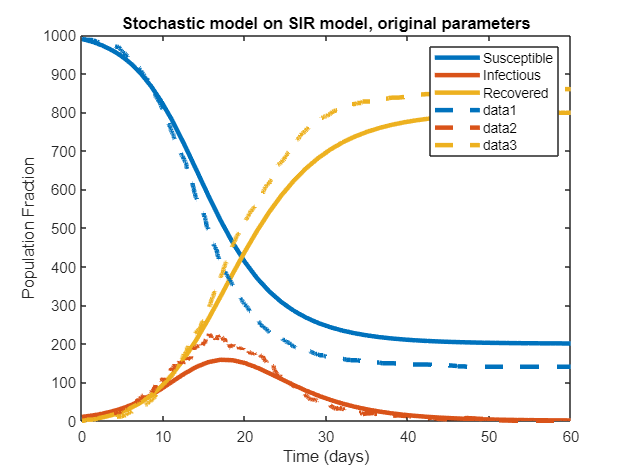

% Run the ODE model

pars.c = 20; % Contacts per unit time (e.g., days)
pars.p = 0.025; % Probability of infectious contact
pars.beta = pars.c*pars.p; % Transmission rate
pars.gamma = 1/4; %
pars.tf=60;
pars.R0 = pars.beta/pars.gamma;
pars.N = 1000;
pars.I0= 10;
pars.S0= pars.N-pars.I0;

[t,y]=ode45(@(t,y) sir_model(t,y,pars),[0 pars.tf],[pars.S0 pars.I0 0]/pars.N);
figure(56); 
tmph=plot(t,pars.N*y);
title('Stochastic model on SIR model, original parameters'); 
xlabel('Time (days)');
ylabel('Population Fraction'); 
legend('Susceptible', 'Infectious', 'Recovered');
set(tmph,'linewidth',3);
hold on

% Run the stochastic model
[tsim,ysim]=stochsim_SIR([0 pars.tf],[pars.S0 pars.I0 0],pars);
tmphsim=plot(tsim,ysim,'--');
set(tmphsim,'linewidth',3);

% Color the lines the same way (where dashes are for stochastic)
for i=1:3
set(tmphsim(i),'color',get(tmph(i),'color'));

legend;
end



%% the dashed lines are following the shapes of the curves but the trajectories are leading 
% to dropping a little too early or increasing too early. For example, I
% noticed that the stochastic model for susceptible fraction decreased at a
% faster rate than the deterministic model. 


function [t,y] = stochsim_SIR(trange,y0,pars)
% function [t,y] = stochsim_SIR(trange,y0,pars)
%
% Simulates an SIR model via the Gillespie algorithm
% from t0 to tf in trange given initial
% conditions in y0 = [S0 I0 R0] and parameters
% in pars. Returns time and values
% Conditions
t0=trange(1);
tf=trange(2);
t(1)=t0;
y(1,:)=y0;
tcur=t0;
ycur=y0;
ind=1;
% Model
while (tcur<tf)
% Check to see if there is an infection
    if (ycur(2)==0)
        ind=ind+1;
        t(ind)=tf;
        y(ind,:)=ycur;
        break;
    end

    % Rates
    infrate = (pars.beta * ycur(1) * ycur(2))/ pars.N; % infection rate 
    recrate = pars.gamma * ycur(2); % recovery rate
    totrate = infrate + recrate;
    dt = -1/totrate*log(rand);
    tcur=tcur+dt;
    % Event type
    if (rand<(infrate/totrate)) % infection
    ycur(1) = ycur(1) -1; 
    ycur(2) = ycur(2) +1;
    else % recovery
    ycur(2) = ycur(2) - 1; 
    ycur(3) = ycur(3) + 1;
    end
    ind=ind+1;
    t(ind)=tcur;
    y(ind,:)=ycur;
end
end

function dydt = si_model(t,y,pars)
% function dydt = si_model(t,y,pars)
% SI Model
S=y(1);
I=y(2);
% The model
dSdt = -pars.beta*S*I+pars.gamma*I;
dIdt = pars.beta*S*I-pars.gamma*I;
dydt = [dSdt; dIdt];
end

function dydt = sir_model(t,y,pars)
% function dydt = sir_model(t,y,pars)
% SIR Model
S=y(1);
I=y(2);
% The model
dSdt = -pars.beta*S*I;
dIdt = pars.beta*S*I-pars.gamma*I;
dRdt = pars.gamma*I;
dydt = [dSdt; dIdt; dRdt];
end